% dwell_time_disc_sim.mlx - Simulate the relationship between measured and actual dwells
% This script calculates the answer to two questions:
% 1) If a dwell time is measured to have a length of n (integer) frames, 
% what is the pdf p(t) that the actual length is t (real)?
% 2) If the actual length is t, what is the probability e(t) 
% that the event is detected?
% The script assumes a model of the dwell begin/end detection algorithm that
% is defined by the parameters fb and fe as defined below.  These parameters
% must be set as global variables before running script.   Discrimination
% is non-hysteretic when fb = 1 - fe.
% Outputs are graphs and the structure disc_sim_results.


Copyright 2016 Jeff Gelles, Brandeis University

This is licensed software; see notice at end of file. 

Calculation assumes a frame duration of one time unit. fb and fe as defined in notes:

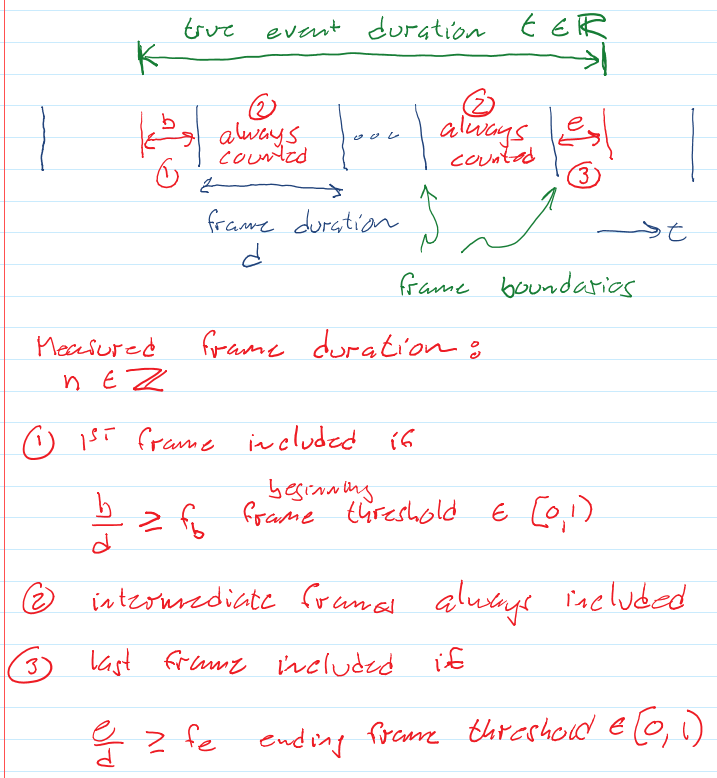

% parameters
nsims = 50000;
aw = 6; % range of simulations (in units of measured frame length)
ro = aw - 2; % range of output


% set up output
fstring = ['_fb' num2str(fb) '_fe' num2str(fe)];
disc_sim_results = [];
disc_sim_results.fb = fb;
disc_sim_results.fe = fe;
disc_sim_results.fstring = fstring;
disc_sim_results.prog = 'dwell_time_disc_sim.mlx';
disc_sim_results.ver = jganalyze_gitinfo();

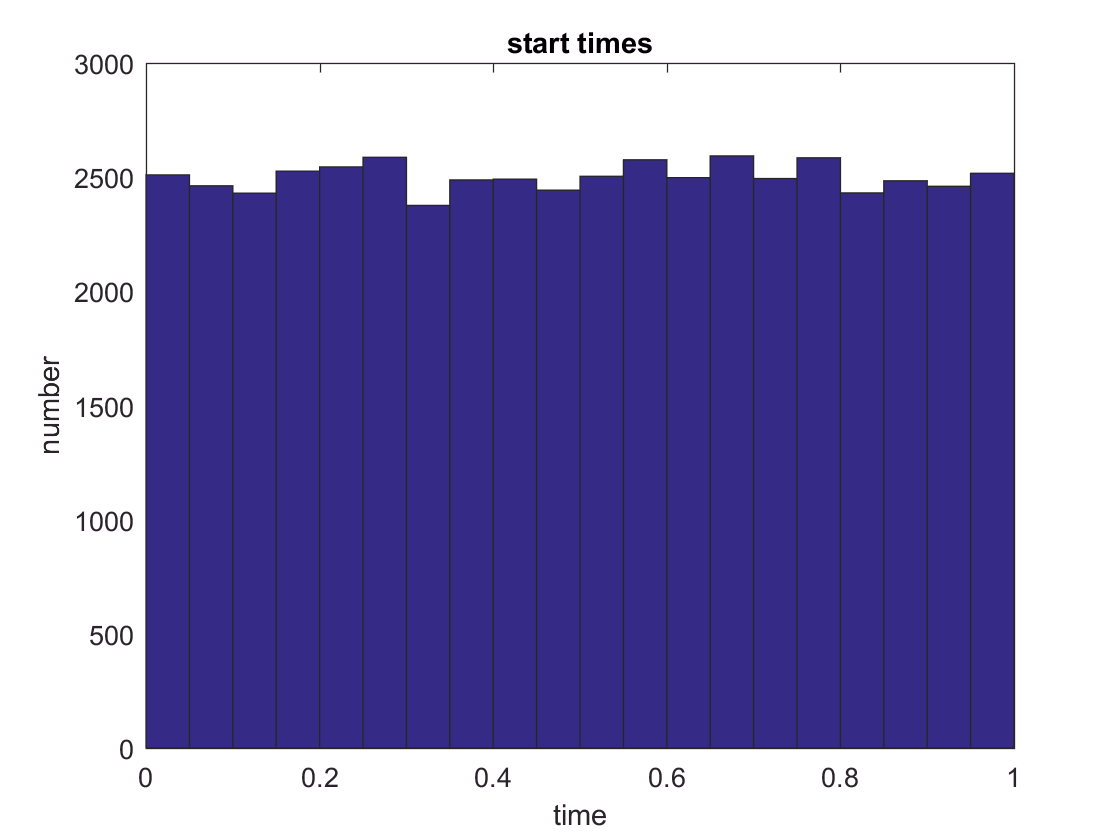

% Generate a flat distribution of event lengths in (0, aw) that start at (0, 1)
t = aw .* rand(nsims, 1);
t_start = rand(nsims, 1);
t_end = t_start + t;
hist(t_start, 20);
xlabel('time (frames)');
ylabel('number');
title('start times');

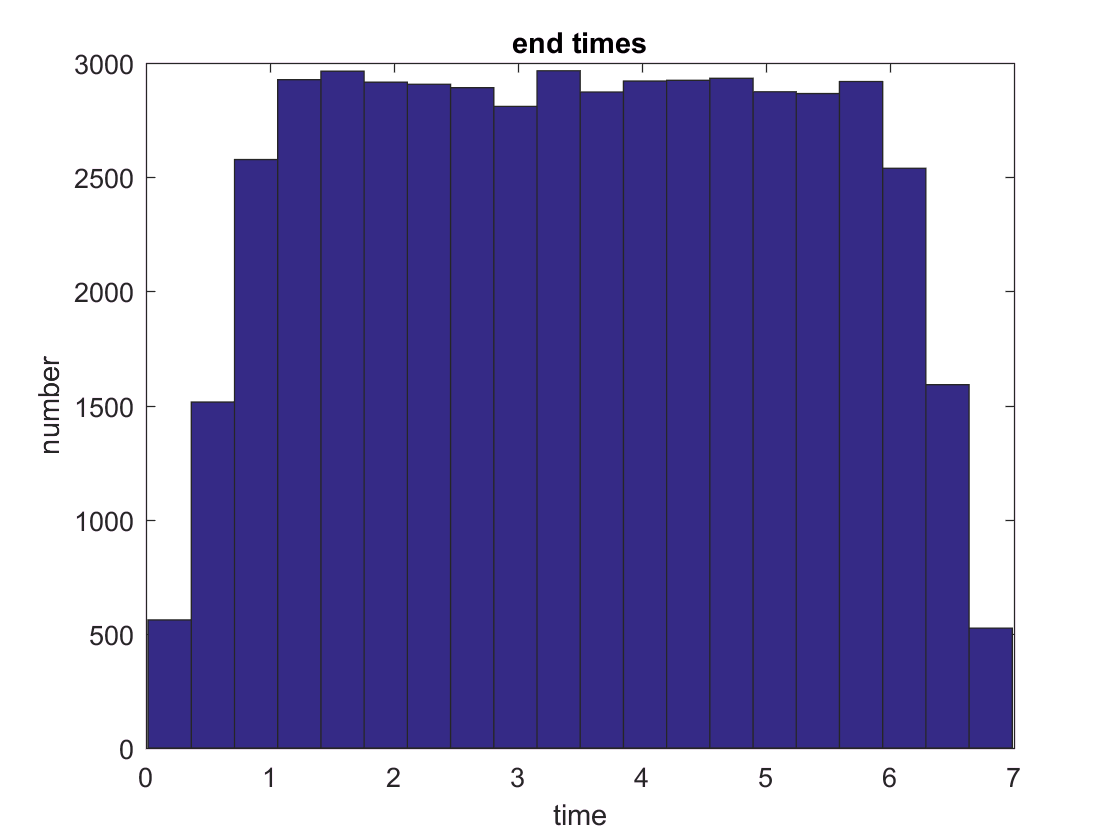

hist(t_end, 20);
xlabel('time (frames)');
ylabel('number');
title('end times');

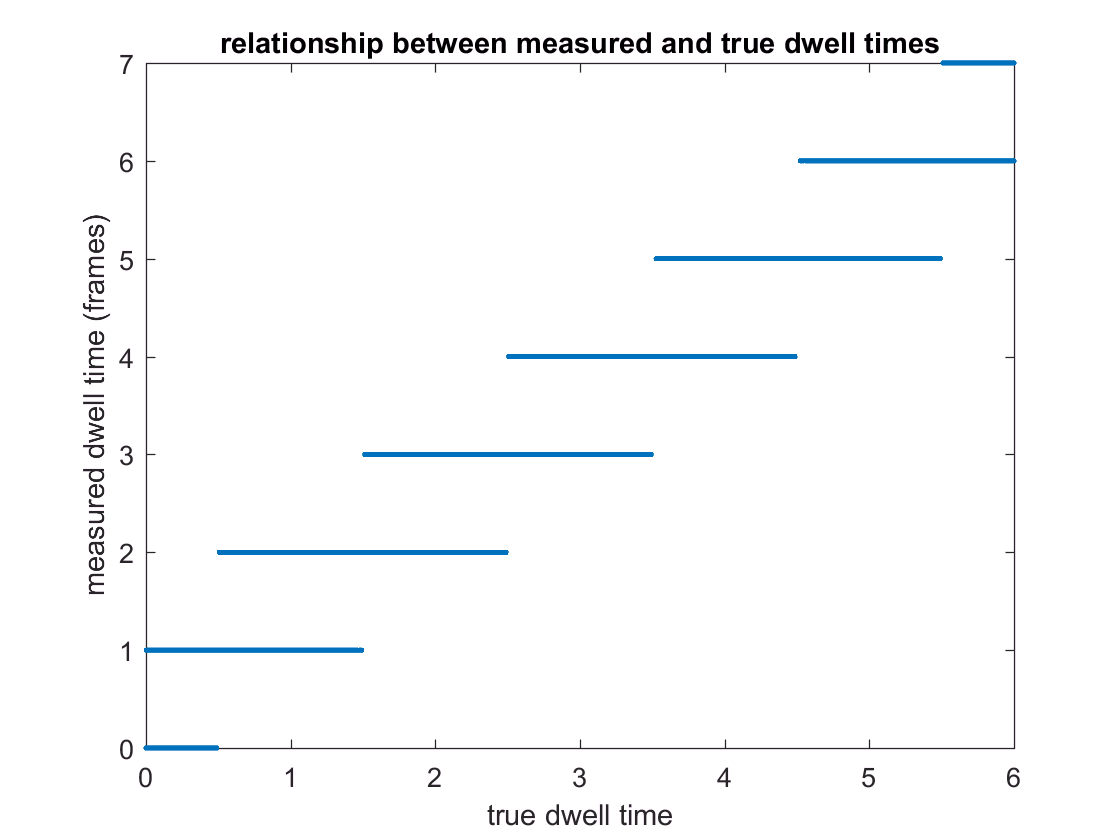

% find detected duration in frames for each event
[n_start, n_end, n] = discrim_model_2parm(t_start, t_end, fb, fe);
plot (t, n, '.');
xlabel('true dwell time (frames)');
ylabel('measured dwell time (frames)');
title('relationship between measured and true dwell times');

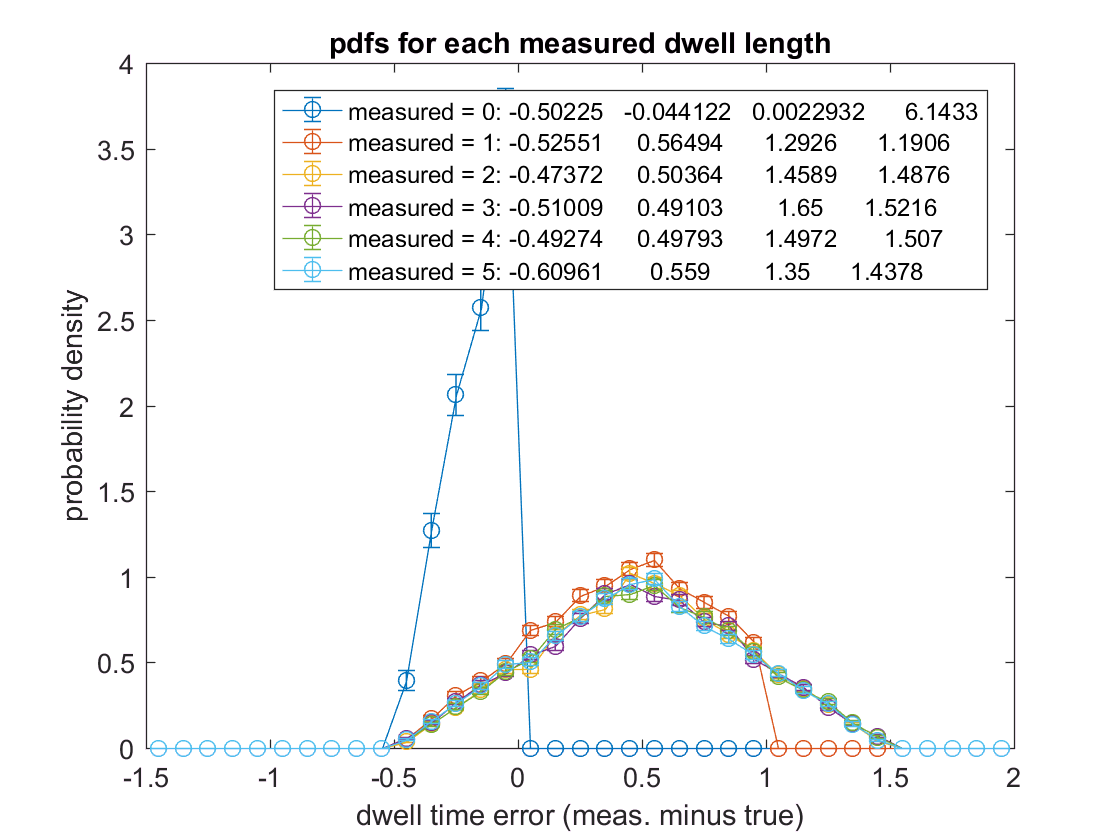

% plot pdfs for each measured dwell length
bin_edges = -1.5:0.1:2.0;
leg = cell(ro + 1, 1);
fig1 = figure();
for i = 0:ro
    nn = n == i;
    [bin_centers, y, ~, se] = binned_pdf(n(nn) - t(nn), bin_edges);
    errorbar(bin_centers, y, se, 'o-');
    hold on;
    fitparm(i + 1, :) = trunctriangle_chisq_fit(1, bin_centers, y');
    leg(i + 1) = {['measured = ' num2str(i) ': ' ...
        num2str(fitparm(i + 1, :))]};
end
hold off
disc_sim_results.fitparm = fitparm;
xlabel('dwell time error (meas. minus true; frames)');
ylabel('probability density');
legend(leg);
title(['pdfs for each measured dwell length' fstring], 'Interpreter', 'none');

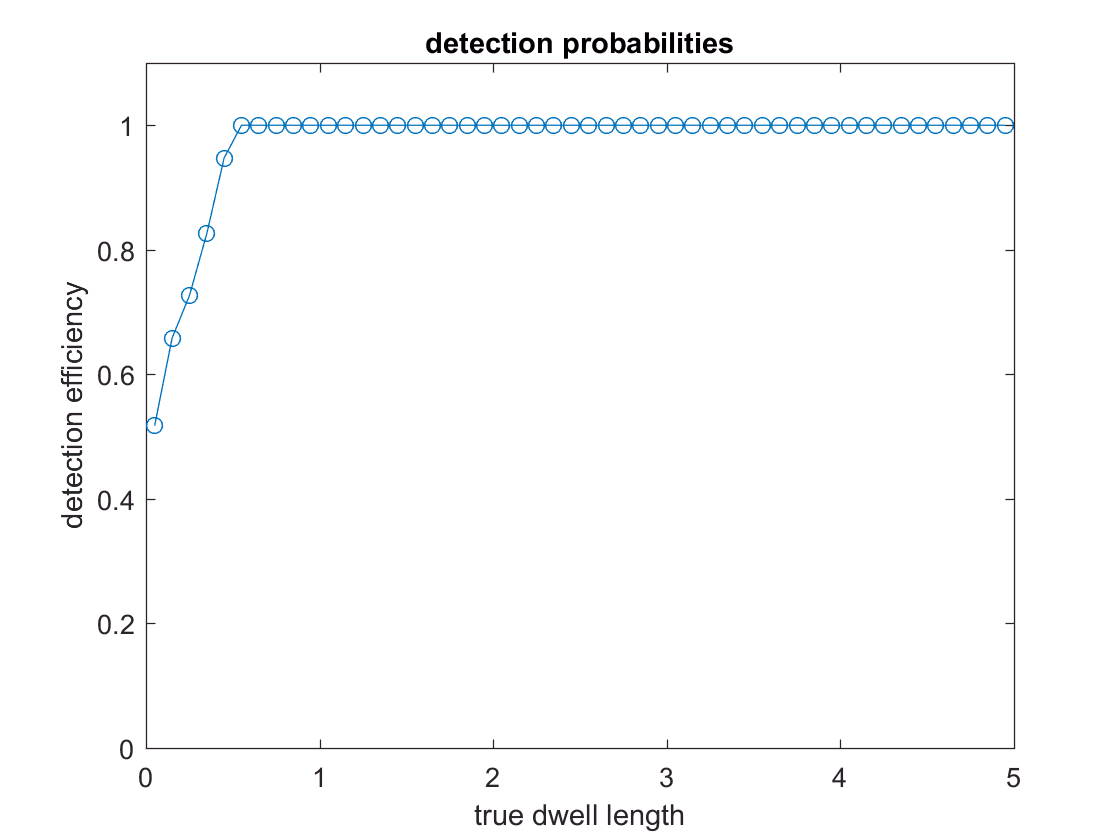

% detection probability (e.g., detected length > 0) distribution
binedges = 0:0.1:ro;
eff = histcounts(t(n > 0),binedges) ./ histcounts(t,binedges);
fig2 = figure();
truevals = 0.05:0.1:(ro - 0.05);
plot(truevals, eff, 'o-');
ylim ([0 1.1]);
xlabel('true dwell length (frames)');
ylabel('detection efficiency');
title(['detection probabilities' fstring], 'Interpreter', 'none');

disc_sim_results.truevals = truevals;
disc_sim_results.eff = eff;

% output
save(['dwell_time_disc_sim' fstring '.mat'],'disc_sim_results', '-mat');
savefig(fig1, ['dwell_time_disc_sim' fstring '_fig1.fig']);
savefig(fig2, ['dwell_time_disc_sim' fstring '_fig2.fig']);

%% notice
% This is free software: you can redistribute it and/or modify it under the
% terms of the GNU General Public License as published by the Free Software
% Foundation, either version 3 of the License, or (at your option) any later
% version.
%
% This software is distributed in the hope that it will be useful, but WITHOUT ANY
% WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR
% A PARTICULAR PURPOSE. See the GNU General Public License for more details.
% You should have received a copy of the GNU General Public License
% along with this software. If not, see <http://www.gnu.org/licenses/>.